clc; clear; close all;
rng(1);

nrep = 1000;
ncoex_vec = zeros(1, nrep);
row_tot_sd = zeros(1, nrep);

for k = 1:nrep
    k
    nspec = 10;
    nm = 3;
    np = 8;
    p_length = 10;
    
    polys = zeros(np, nm);
    for i = 1:np
        polys(i, :) = create_poly(p_length, nm);
    end
    
    cons_traits_mono = rand(nspec, nm);
    %cons_traits_mono = cons_traits_mono ./ sum(cons_traits_mono, 2);    
    
    C = zeros(nspec, np);
    for i = 1:nspec
        C(i, :) = sum((polys' .* cons_traits_mono(i, :)')', 2);
    end
    C = (C * nm) / 50;
    
    params.nspec = nspec;
    params.np = np;
    params.alpha = 0 * ones(nspec, 1);
    params.r = 500 * ones(np, 1);
    params.K = ones(np, 1);
    params.m = 0.2 * ones(nspec, 1);
    params.C = C;
    
    init_abuns = ones(1, params.nspec) * 5;
    init_res = ones(1, params.np) * 5;
    init_state = [init_abuns, init_res];
    
    tspan = [0 10000];
    [t, sim] = ode45(@(t, y) macarthur_eqns(t, y, params), tspan, init_state);
    
    eql = sim(end, :);
    eql_abuns = eql(1:nspec);
    num_coexist = sum(eql_abuns > 0.1);
    
    row_tot_sd(k) = std(sum(C,2));
    ncoex_vec(k) = num_coexist;
end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 50

k = 51

k = 52

k = 53

k = 54

k = 55

k = 56

k = 57

k = 58

k = 59

k = 60

k = 61

k = 62

k = 63

k = 64

k = 65

k = 66

k = 67

k = 68

k = 69

k = 70

k = 71

k = 72

k = 73

k = 74

k = 75

k = 76

k = 77

k = 78

k = 79

k = 80

k = 81

k = 82

k = 83

k = 84

k = 85

k = 86

k = 87

k = 88

k = 89

k = 90

k = 91

k = 92

k = 93

k = 94

k = 95

k = 96

k = 97

k = 98

k = 99

k = 100

k = 101

k = 102

k = 103

k = 104

k = 105

k = 106

k = 107

k = 108

k = 109

k = 110

k = 111

k = 112

k = 113

k = 114

k = 115

k = 116

k = 117

k = 118

k = 119

k = 120

k = 121

k = 122

k = 123

k = 124

k = 125

k = 126

k = 127

k = 128

k = 129

k = 130

k = 131

k = 132

k = 133

k = 134

k = 135

k = 136

k = 137

k = 138

k = 139

k = 140

k = 141

k = 142

k = 143

k = 144

k = 145

k = 146

k = 147

k = 148

k = 149

k = 150

k = 151

k = 152

k = 153

k = 154

k = 155

k = 156

k = 157

k = 158

k = 159

k = 160

k = 161

k = 162

k = 163

k = 164

k = 165

k = 166

k = 167

k = 168

k = 169

k = 170

k = 171

k = 172

k = 173

k = 174

k = 175

k = 176

k = 177

k = 178

k = 179

k = 180

k = 181

k = 182

k = 183

k = 184

k = 185

k = 186

k = 187

k = 188

k = 189

k = 190

k = 191

k = 192

k = 193

k = 194

k = 195

k = 196

k = 197

k = 198

k = 199

k = 200

k = 201

k = 202

k = 203

k = 204

k = 205

k = 206

k = 207

k = 208

k = 209

k = 210

k = 211

k = 212

k = 213

k = 214

k = 215

k = 216

k = 217

k = 218

k = 219

k = 220

k = 221

k = 222

k = 223

k = 224

k = 225

k = 226

k = 227

k = 228

k = 229

k = 230

k = 231

k = 232

k = 233

k = 234

k = 235

k = 236

k = 237

k = 238

k = 239

k = 240

k = 241

k = 242

k = 243

k = 244

k = 245

k = 246

k = 247

k = 248

k = 249

k = 250

k = 251

k = 252

k = 253

k = 254

k = 255

k = 256

k = 257

k = 258

k = 259

k = 260

k = 261

k = 262

k = 263

k = 264

k = 265

k = 266

k = 267

k = 268

k = 269

k = 270

k = 271

k = 272

k = 273

k = 274

k = 275

k = 276

k = 277

k = 278

k = 279

k = 280

k = 281

k = 282

k = 283

k = 284

k = 285

k = 286

k = 287

k = 288

k = 289

k = 290

k = 291

k = 292

k = 293

k = 294

k = 295

k = 296

k = 297

k = 298

k = 299

k = 300

k = 301

k = 302

k = 303

k = 304

k = 305

k = 306

k = 307

k = 308

k = 309

k = 310

k = 311

k = 312

k = 313

k = 314

k = 315

k = 316

k = 317

k = 318

k = 319

k = 320

k = 321

k = 322

k = 323

k = 324

k = 325

k = 326

k = 327

k = 328

k = 329

k = 330

k = 331

k = 332

k = 333

k = 334

k = 335

k = 336

k = 337

k = 338

k = 339

k = 340

k = 341

k = 342

k = 343

k = 344

k = 345

k = 346

k = 347

k = 348

k = 349

k = 350

k = 351

k = 352

k = 353

k = 354

k = 355

k = 356

k = 357

k = 358

k = 359

k = 360

k = 361

k = 362

k = 363

k = 364

k = 365

k = 366

k = 367

k = 368

k = 369

k = 370

k = 371

k = 372

k = 373

k = 374

k = 375

k = 376

k = 377

k = 378

k = 379

k = 380

k = 381

k = 382

k = 383

k = 384

k = 385

k = 386

k = 387

k = 388

k = 389

k = 390

k = 391

k = 392

k = 393

k = 394

k = 395

k = 396

k = 397

k = 398

k = 399

k = 400

k = 401

k = 402

k = 403

k = 404

k = 405

k = 406

k = 407

k = 408

k = 409

k = 410

k = 411

k = 412

k = 413

k = 414

k = 415

k = 416

k = 417

k = 418

k = 419

k = 420

k = 421

k = 422

k = 423

k = 424

k = 425

k = 426

k = 427

k = 428

k = 429

k = 430

k = 431

k = 432

k = 433

k = 434

k = 435

k = 436

k = 437

k = 438

k = 439

k = 440

k = 441

k = 442

k = 443

k = 444

k = 445

k = 446

k = 447

k = 448

k = 449

k = 450

k = 451

k = 452

k = 453

k = 454

k = 455

k = 456

k = 457

k = 458

k = 459

k = 460

k = 461

k = 462

k = 463

k = 464

k = 465

k = 466

k = 467

k = 468

k = 469

k = 470

k = 471

k = 472

k = 473

k = 474

k = 475

k = 476

k = 477

k = 478

k = 479

k = 480

k = 481

k = 482

k = 483

k = 484

k = 485

k = 486

k = 487

k = 488

k = 489

k = 490

k = 491

k = 492

k = 493

k = 494

k = 495

k = 496

k = 497

k = 498

k = 499

k = 500

k = 501

k = 502

k = 503

k = 504

k = 505

k = 506

k = 507

k = 508

k = 509

k = 510

k = 511

k = 512

k = 513

k = 514

k = 515

k = 516

k = 517

k = 518

k = 519

k = 520

k = 521

k = 522

k = 523

k = 524

k = 525

k = 526

k = 527

k = 528

k = 529

k = 530

k = 531

k = 532

k = 533

k = 534

k = 535

k = 536

k = 537

k = 538

k = 539

k = 540

k = 541

k = 542

k = 543

k = 544

k = 545

k = 546

k = 547

k = 548

k = 549

k = 550

k = 551

k = 552

k = 553

k = 554

k = 555

k = 556

k = 557

k = 558

k = 559

k = 560

k = 561

k = 562

k = 563

k = 564

k = 565

k = 566

k = 567

k = 568

k = 569

k = 570

k = 571

k = 572

k = 573

k = 574

k = 575

k = 576

k = 577

k = 578

k = 579

k = 580

k = 581

k = 582

k = 583

k = 584

k = 585

k = 586

k = 587

k = 588

k = 589

k = 590

k = 591

k = 592

k = 593

k = 594

k = 595

k = 596

k = 597

k = 598

k = 599

k = 600

k = 601

k = 602

k = 603

k = 604

k = 605

k = 606

k = 607

k = 608

k = 609

k = 610

k = 611

k = 612

k = 613

k = 614

k = 615

k = 616

k = 617

k = 618

k = 619

k = 620

k = 621

k = 622

k = 623

k = 624

k = 625

k = 626

k = 627

k = 628

k = 629

k = 630

k = 631

k = 632

k = 633

k = 634

k = 635

k = 636

k = 637

k = 638

k = 639

k = 640

k = 641

k = 642

k = 643

k = 644

k = 645

k = 646

k = 647

k = 648

k = 649

k = 650

k = 651

k = 652

k = 653

k = 654

k = 655

k = 656

k = 657

k = 658

k = 659

k = 660

k = 661

k = 662

k = 663

k = 664

k = 665

k = 666

k = 667

k = 668

k = 669

k = 670

k = 671

k = 672

k = 673

k = 674

k = 675

k = 676

k = 677

k = 678

k = 679

k = 680

k = 681

k = 682

k = 683

k = 684

k = 685

k = 686

k = 687

k = 688

k = 689

k = 690

k = 691

k = 692

k = 693

k = 694

k = 695

k = 696

k = 697

k = 698

k = 699

k = 700

k = 701

k = 702

k = 703

k = 704

k = 705

k = 706

k = 707

k = 708

k = 709

k = 710

k = 711

k = 712

k = 713

k = 714

k = 715

k = 716

k = 717

k = 718

k = 719

k = 720

k = 721

k = 722

k = 723

k = 724

k = 725

k = 726

k = 727

k = 728

k = 729

k = 730

k = 731

k = 732

k = 733

k = 734

k = 735

k = 736

k = 737

k = 738

k = 739

k = 740

k = 741

k = 742

k = 743

k = 744

k = 745

k = 746

k = 747

k = 748

k = 749

k = 750

k = 751

k = 752

k = 753

k = 754

k = 755

k = 756

k = 757

k = 758

k = 759

k = 760

k = 761

k = 762

k = 763

k = 764

k = 765

k = 766

k = 767

k = 768

k = 769

k = 770

k = 771

k = 772

k = 773

k = 774

k = 775

k = 776

k = 777

k = 778

k = 779

k = 780

k = 781

k = 782

k = 783

k = 784

k = 785

k = 786

k = 787

k = 788

k = 789

k = 790

k = 791

k = 792

k = 793

k = 794

k = 795

k = 796

k = 797

k = 798

k = 799

k = 800

k = 801

k = 802

k = 803

k = 804

k = 805

k = 806

k = 807

k = 808

k = 809

k = 810

k = 811

k = 812

k = 813

k = 814

k = 815

k = 816

k = 817

k = 818

k = 819

k = 820

k = 821

k = 822

k = 823

k = 824

k = 825

k = 826

k = 827

k = 828

k = 829

k = 830

k = 831

k = 832

k = 833

k = 834

k = 835

k = 836

k = 837

k = 838

k = 839

k = 840

k = 841

k = 842

k = 843

k = 844

k = 845

k = 846

k = 847

k = 848

k = 849

k = 850

k = 851

k = 852

k = 853

k = 854

k = 855

k = 856

k = 857

k = 858

k = 859

k = 860

k = 861

k = 862

k = 863

k = 864

k = 865

k = 866

k = 867

k = 868

k = 869

k = 870

k = 871

k = 872

k = 873

k = 874

k = 875

k = 876

k = 877

k = 878

k = 879

k = 880

k = 881

k = 882

k = 883

k = 884

k = 885

k = 886

k = 887

k = 888

k = 889

k = 890

k = 891

k = 892

k = 893

k = 894

k = 895

k = 896

k = 897

k = 898

k = 899

k = 900

k = 901

k = 902

k = 903

k = 904

k = 905

k = 906

k = 907

k = 908

k = 909

k = 910

k = 911

k = 912

k = 913

k = 914

k = 915

k = 916

k = 917

k = 918

k = 919

k = 920

k = 921

k = 922

k = 923

k = 924

k = 925

k = 926

k = 927

k = 928

k = 929

k = 930

k = 931

k = 932

k = 933

k = 934

k = 935

k = 936

k = 937

k = 938

k = 939

k = 940

k = 941

k = 942

k = 943

k = 944

k = 945

k = 946

k = 947

k = 948

k = 949

k = 950

k = 951

k = 952

k = 953

k = 954

k = 955

k = 956

k = 957

k = 958

k = 959

k = 960

k = 961

k = 962

k = 963

k = 964

k = 965

k = 966

k = 967

k = 968

k = 969

k = 970

k = 971

k = 972

k = 973

k = 974

k = 975

k = 976

k = 977

k = 978

k = 979

k = 980

k = 981

k = 982

k = 983

k = 984

k = 985

k = 986

k = 987

k = 988

k = 989

k = 990

k = 991

k = 992

k = 993

k = 994

k = 995

k = 996

k = 997

k = 998

k = 999

k = 1000

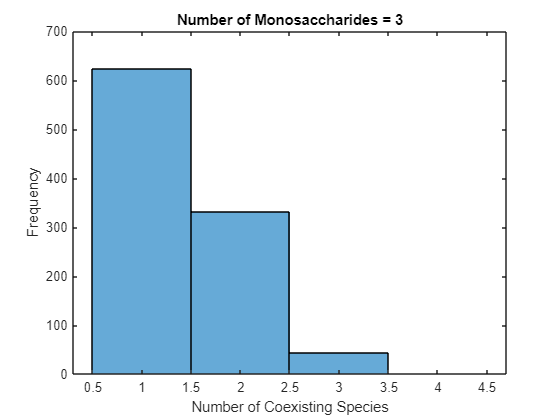


figure;
histogram(ncoex_vec);
title(['Number of Monosaccharides = ', num2str(nm)]);
xlabel('Number of Coexisting Species');
ylabel('Frequency');


corr(row_tot_sd(:), ncoex_vec(:), type = 'Pearson')

ans = -0.2093

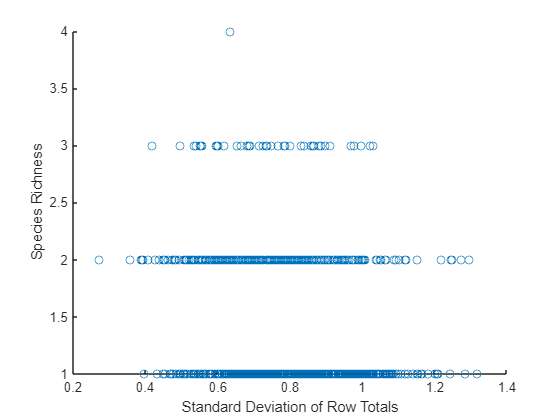

scatter(row_tot_sd, ncoex_vec)
xlabel('Standard Deviation of Row Totals');
ylabel('Species Richness');

function counts = create_poly(p_length, nm)
    vec = randi(nm, 1, p_length);
    counts = histcounts(vec, 1:(nm+1));
end

function dydt = macarthur_eqns(~, state, params)
    N = state(1:params.nspec);
    R = state((params.nspec + 1):end);

    dNdt = params.alpha + N .* ((params.C * R) - params.m);
    dRdt = R .* (params.r .* (1 - R ./ params.K) - (params.C' * N));
    
    dydt = [dNdt; dRdt];
end